cam = webcam('C270 HD WEBCAM','resolution','1280x720')

cam =   webcam with properties:

                     Name: 'C270 HD WEBCAM'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x176'  '320x240'  '352x288'  '432x240'  '544x288'  '640x360'  '752x416'  '800x448'  '800x600'  '864x480'  '960x544'  '960x720'  '1024x576'  '1184x656'  '1280x720'}
               Resolution: '1280x720'
                Sharpness: 24
                     Gain: 24
             WhiteBalance: 2800
                 Exposure: -4
         WhiteBalanceMode: 'auto'
               Brightness: 128
    BacklightCompensation: 1
             ExposureMode: 'auto'
               Saturation: 32
                 Contrast: 32


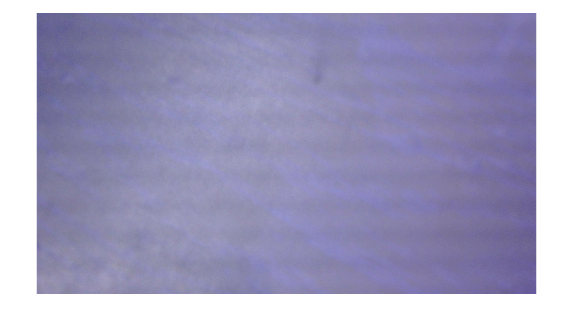

img = snapshot(cam);
imshow(img)

rgb_list = size(img)

rgb_list =          720        1280           3


rgb_rows = rgb_list(1)

rgb_rows = 720

rgb_cols = rgb_list(2)

rgb_cols = 1280

red = img(:,:,1);
green = img(:,:,2);
blue = img(:,:,3);

total = rgb_rows*rgb_cols

total = 921600

red_sum = sum(red,"all");
green_sum = sum(green,"all");
blue_sum = sum(blue,"all");

new_red = red_sum/total

new_red = 134.4822

new_blue = blue_sum/total

new_blue = 172.9991

new_green = green_sum/total

new_green = 131.0239

rgb_means = [new_red, new_blue, new_green]

rgb_means =   134.4822  172.9991  131.0239


if max(rgb_means) == new_red
    disp("Color is RED.")
elseif max(rgb_means) == new_blue
    disp("Color is BLUE.")
else
    disp("Color is GREEN.")
end

Color is BLUE.
